# Import Relevant Files Again

burnsideDir = fullfile("Sky Classified Burnside.csv");
gaultBaseDir = fullfile("Sky Classified Gault.csv");

burnsideDataUntitled = readtimetable(burnsideDir);
gaultDataUntitled = readtimetable(gaultBaseDir);

# Recompile Once Again

% Do the agonizing recompiling
allVariables = 1:width(burnsideDataUntitled);

% Fix the column titles & extract wavenumber
wavenumbers = round(table2array(burnsideDataUntitled(1, 1:end-1)), 3);

wavenumberTitles = arrayfun(@(x) num2str(x), wavenumbers, 'UniformOutput', false);

newTitle = string([wavenumberTitles, {"Clouds"}]);
burnsideDataUntitled(1, :) = [];
gaultDataUntitled(1, :) = [];

% Annoying that I have to do this, but whatever

burnsideData = renamevars(burnsideDataUntitled, allVariables, newTitle);
gaultData = renamevars(gaultDataUntitled, allVariables, newTitle);

# Synchronize time data

% Convert to the nearest minute
burnsideData.Properties.RowTimes = dateshift(burnsideData.Properties.RowTimes, 'start', 'minute', 'current');
gaultData.Properties.RowTimes = dateshift(gaultData.Properties.RowTimes, 'start', 'minute', 'current');

% Make a uniform time series
timeVector = min([burnsideData.Time; gaultData.Time]):minutes(8):max([burnsideData.Time; gaultData.Time]);

% Use synchronize to make sure that later differences will be accepted
synchBurn = synchronize(burnsideData, timeVector, "fillwithmissing");
synchGault = synchronize(gaultData, timeVector, 'fillwithmissing');

# Divide into Cloudy and Clear Tables and Synch Again

% Divide into separate tables
clearBurnsideData = burnsideData(burnsideData.("Clouds")==0, :);
cloudyBurnsideData = burnsideData(burnsideData.("Clouds") == 1, :);

clearGaultData = gaultData(gaultData.("Clouds")==0, :);
cloudyGaultData = gaultData(gaultData.("Clouds") == 1, :);

% Synch all tables again using NaN values

% Synchronize the clear data tables to ensure uniformity
synchClearBurn = synchronize(clearBurnsideData, timeVector, 'fillwithmissing');
synchCloudyBurn = synchronize(cloudyBurnsideData, timeVector, 'fillwithmissing');
synchClearGault = synchronize(clearGaultData, timeVector, 'fillwithmissing');
synchCloudyGault = synchronize(cloudyGaultData, timeVector, 'fillwithmissing');

# Find Full Means and Create Tables for Divided Data

dividedTitles = {'wavenumbers', 'burnsideFull', ... 
    'gaultFull', 'burnsideClear', 'gaultClear', 'burnsideCloudy', 'gaultCloudy'};

dividedTitles = 1×7 cell array
    {'wavenumbers'}    {'burnsideFull'}    {'gaultFull'}    {'burnsideClear'}    {'gaultClear'}    {'burnsideCloudy'}    {'gaultCloudy'}


% Create tables
tableMeansUntitled = table(zeros(length(allVariables), 7));
tableMeans = renamevars(splitvars(tableMeansUntitled), 1:7, dividedTitles); 

tableSTDUntitled = table(zeros(length(allVariables), 7));
tableSTD = renamevars(splitvars(tableSTDUntitled), 1:7, dividedTitles);

% Fill tables with Burnside Right and Gault Left
tableMeans(:, 1) = table(str2double(newTitle'));
tableMeans(:, 2) = table((mean(synchBurn.Variables, 1, 'omitnan'))');
tableMeans(:, 3) = table((mean(synchGault.Variables, 1, 'omitnan'))');
tableMeans(:, 4) = table(mean(synchClearBurn.Variables, 1, 'omitnan')');
tableMeans(:, 5) = table(mean(synchClearGault.Variables, 1, 'omitnan')');
tableMeans(:, 6) = table(mean(synchCloudyBurn.Variables, 1, 'omitnan')');
tableMeans(:, 7) = table(mean(synchCloudyGault.Variables, 1, 'omitnan')');

tableSTD(:, 1) = table(str2double(newTitle'));
tableSTD(:, 2) = table(std(synchBurn.Variables, 0, 1, 'omitnan')');
tableSTD(:, 3) = table(std(synchGault.Variables, 0, 1, 'omitnan')');
tableSTD(:, 4) = table(std(synchClearBurn.Variables, 0, 1, 'omitnan')');
tableSTD(:, 5) = table(std(synchClearGault.Variables, 0, 1, 'omitnan')');
tableSTD(:, 6) = table(std(synchCloudyBurn.Variables, 0, 1, 'omitnan')');
tableSTD(:, 7) = table(std(synchCloudyGault.Variables, 0, 1, 'omitnan')');

# Clould Also Use Only Sections Which Overlap

% [tf1, overlapIndexBurnFull] = overlapsrange(burnsideData, gaultData.Time);
% [tf2, overlapIndexBurnClear] = overlapsrange(clearBurnsideData, clearGaultData.Time);
% [tf3, overlapIndexBurnCloudy] = overlapsrange(cloudyBurnsideData, cloudyGaultData.Time);
% 
% overlapFullBurn = burnsideData(overlapIndexBurnFull, :);
% overlapClearBurn = clearBurnsideData(overlapIndexBurnClear, :);
% overlapCloudyBurn = cloudyBurnsideData(overlapIndexBurnCloudy, :);
% 
% [tf4, overlapIndexGaultFull] = overlapsrange(gaultData, burnsideData.Time);
% [tf5, overlapIndexGaultClear] = overlapsrange(clearGaultData, clearBurnsideData.Time);
% [tf6, overlapIndexGaultCloudy] = overlapsrange(cloudyGaultData, cloudyBurnsideData.Time);
% 
% overlapFullGault = gaultData(overlapIndexGaultFull, :);
% overlapClearGault = clearGaultData(overlapIndexGaultClear, :);
% overlapCloudyGault = cloudyGaultData(overlapIndexGaultCloudy, :);

# Calculate Basic Differences

% STD of a difference is the sum of the standard deviations in quadrature
% Full Difference 
fullDiff = synchBurn - synchGault;
meanFullDiff = mean(fullDiff.Variables, 1, 'omitnan');
stdFullDiff = sqrt(var(synchBurn.Variables, 0, 1, 'omitnan') + var(synchGault.Variables, 0, 1, 'omitnan'));

% Clear Difference
clearDiff = synchClearBurn - synchClearGault;
meanClearDiff = mean(clearDiff.Variables, 1, 'omitnan');
stdClearDiff = sqrt(var(synchClearBurn.Variables, 0, 1, 'omitnan') + var(synchClearGault.Variables, 0, 1, 'omitnan'));

% Cloudy Difference
cloudyDiff = synchCloudyBurn - synchCloudyGault;
meanCloudyDiff = mean(cloudyDiff.Variables, 1, 'omitnan');
stdCloudyDiff = sqrt(var(synchCloudyBurn.Variables, 0, 1, 'omitnan') + var(synchCloudyGault.Variables, 0, 1, 'omitnan'));

% Convert to tables arranged vertically so that ggplot can read them, with wavenumbers as the first column 
wavenumberMeans = table(str2double(newTitle'), meanFullDiff', meanClearDiff', meanCloudyDiff',  'VariableNames', {'Wavenumbers', 'Full Sky', 'Clear', 'Cloudy'});
   
% wavenumberMeans = renamevars(splitvars(wavenumberMeansUntitled), allVariables, newTitle);
wavenumberSTD = table(str2double(newTitle'), stdFullDiff', stdClearDiff', stdCloudyDiff', 'VariableNames', {'Wavenumbers', 'Full Sky', 'Clear', 'Cloudy'});
%wavenumberSTD = renamevars(splitvars(wavenumberSTDUntitled), allVariables, newTitle);


# Define Spectral Regions

% Define spectral regions
carbonBand = [540, 800];
ozoneBand = [990, 1080];
methaneBand = [1250, 1350];
atmosphericWindow = [800, 1200];

% Find variable titles using the wavenumbers variable
carbonIndices = wavenumbers(wavenumbers >= carbonBand(1) & wavenumbers <= carbonBand(2));
carbonTitles = arrayfun(@(x) num2str(x), carbonIndices, 'UniformOutput', false);

ozoneIndices = wavenumbers(wavenumbers >= ozoneBand(1) & wavenumbers <= ozoneBand(2));
ozoneTitles = arrayfun(@(x) num2str(x), ozoneIndices, 'UniformOutput', false);

methaneIndices = wavenumbers(wavenumbers >= methaneBand(1) & wavenumbers <= methaneBand(2));
methaneTitles = arrayfun(@(x) num2str(x), methaneIndices, 'UniformOutput', false);

windowIndices = wavenumbers(wavenumbers >= atmosphericWindow(1) & wavenumbers <= atmosphericWindow(2));
windowTitles = arrayfun(@(x) num2str(x), windowIndices, 'UniformOutput', false);



# Calculate Means and STD of Each Region

% Full Sky
averageValues = zeros(height(synchBurn), 6);
standardDeviations = zeros(height(synchBurn), 6);

averageValues(:, 1) = mean(fullDiff.Variables, 2, 'omitnan');
averageValues(:, 2) = mean(table2array(fullDiff(:, carbonTitles)), 2, "omitnan");
averageValues(:, 3) = mean(table2array(fullDiff(:, ozoneTitles)), 2, "omitnan");
averageValues(:, 4) = mean(table2array(fullDiff(:, methaneTitles)), 2, "omitnan");
averageValues(:, 5) = mean(table2array(fullDiff(:, windowTitles)), 2, "omitnan");
averageValues(:, 6) = mean(table2array(fullDiff(:, {'Clouds'})), 2, "omitnan");

standardDeviations(:, 1) = std(fullDiff.Variables, 0, 2, 'omitnan');
standardDeviations(:, 2) = std(table2array(fullDiff(:, carbonTitles)), 0, 2, "omitnan");
standardDeviations(:, 3) = std(table2array(fullDiff(:,ozoneTitles)), 0, 2, "omitnan");
standardDeviations(:, 4) = std(table2array(fullDiff(:, methaneTitles)), 0, 2, "omitnan");
standardDeviations(:, 5) = std(table2array(fullDiff(:, windowTitles)), 0, 2, "omitnan");
standardDeviations(:, 6) = std(table2array(fullDiff(:, {'Clouds'}), 0, 2, "omitnan"));

% Store the average values in a table for better organization
averageDivFullUntitled = timetable(timeVector', averageValues);
averageDivFull = renamevars(splitvars(averageDivFullUntitled), splitvars(averageDivFullUntitled).Properties.VariableNames, {'Total', 'Carbon', 'Ozone', 'Methane', 'AtmosphericWindow', 'Clouds'});
stdDivFullUntitled = timetable(timeVector', standardDeviations);
stdDivFull = renamevars(splitvars(stdDivFullUntitled), splitvars(stdDivFullUntitled).Properties.VariableNames, {'Total', 'Carbon', 'Ozone', 'Methane', 'AtmosphericWindow', 'Clouds'});

% Clear Sky
averageValues = zeros(height(synchBurn), 6);
standardDeviations = zeros(height(synchBurn), 6);

averageValues(:, 1) = mean(clearDiff.Variables, 2, 'omitnan');
averageValues(:, 2) = mean(table2array(clearDiff(:, carbonTitles)), 2, "omitnan");
averageValues(:, 3) = mean(table2array(clearDiff(:, ozoneTitles)), 2, "omitnan");
averageValues(:, 4) = mean(table2array(clearDiff(:, methaneTitles)), 2, "omitnan");
averageValues(:, 5) = mean(table2array(clearDiff(:, windowTitles)), 2, "omitnan");
averageValues(:, 6) = mean(table2array(clearDiff(:, {'Clouds'})), 2, "omitnan");

standardDeviations(:, 1) = std(clearDiff.Variables, 0, 2, 'omitnan');
standardDeviations(:, 2) = std(table2array(clearDiff(:, carbonTitles)), 0, 2, "omitnan");
standardDeviations(:, 3) = std(table2array(clearDiff(:,ozoneTitles)), 0, 2, "omitnan");
standardDeviations(:, 4) = std(table2array(clearDiff(:, methaneTitles)), 0, 2, "omitnan");
standardDeviations(:, 5) = std(table2array(clearDiff(:, windowTitles)), 0, 2, "omitnan");
standardDeviations(:, 6) = std(table2array(clearDiff(:, {'Clouds'}), 0, 2, "omitnan"));

% Store the average values in a table for better organization
averageDivClearUntitled = timetable(timeVector', averageValues);
averageDivClear = renamevars(splitvars(averageDivClearUntitled), splitvars(averageDivClearUntitled).Properties.VariableNames, {'Total', 'Carbon', 'Ozone', 'Methane', 'AtmosphericWindow', 'Clouds'});
stdDivClearUntitled = timetable(timeVector', standardDeviations);
stdDivClear = renamevars(splitvars(stdDivClearUntitled), splitvars(stdDivClearUntitled).Properties.VariableNames, {'Total', 'Carbon', 'Ozone', 'Methane', 'AtmosphericWindow', 'Clouds'});


% Clear Sky
averageValues = zeros(height(synchBurn), 6);
standardDeviations = zeros(height(synchBurn), 6);

averageValues(:, 1) = mean(cloudyDiff.Variables, 2, 'omitnan');
averageValues(:, 2) = mean(table2array(cloudyDiff(:, carbonTitles)), 2, "omitnan");
averageValues(:, 3) = mean(table2array(cloudyDiff(:, ozoneTitles)), 2, "omitnan");
averageValues(:, 4) = mean(table2array(cloudyDiff(:, methaneTitles)), 2, "omitnan");
averageValues(:, 5) = mean(table2array(cloudyDiff(:, windowTitles)), 2, "omitnan");
averageValues(:, 6) = mean(table2array(cloudyDiff(:, {'Clouds'})), 2, "omitnan");

standardDeviations(:, 1) = std(cloudyDiff.Variables, 0, 2, 'omitnan');
standardDeviations(:, 2) = std(table2array(cloudyDiff(:, carbonTitles)), 0, 2, "omitnan");
standardDeviations(:, 3) = std(table2array(cloudyDiff(:,ozoneTitles)), 0, 2, "omitnan");
standardDeviations(:, 4) = std(table2array(cloudyDiff(:, methaneTitles)), 0, 2, "omitnan");
standardDeviations(:, 5) = std(table2array(cloudyDiff(:, windowTitles)), 0, 2, "omitnan");
standardDeviations(:, 6) = std(table2array(cloudyDiff(:, {'Clouds'}), 0, 2, "omitnan"));

% Store the average values in a table for better organization
averageDivCloudyUntitled = timetable(timeVector', averageValues);
averageDivCloudy = renamevars(splitvars(averageDivCloudyUntitled), splitvars(averageDivCloudyUntitled).Properties.VariableNames, {'Total', 'Carbon', 'Ozone', 'Methane', 'AtmosphericWindow', 'Clouds'});
stdDivCloudyUntitled = timetable(timeVector', standardDeviations);
stdDivCloudy = renamevars(splitvars(stdDivCloudyUntitled), splitvars(stdDivCloudyUntitled).Properties.VariableNames, {'Total', 'Carbon', 'Ozone', 'Methane', 'AtmosphericWindow', 'Clouds'});


# Hourly Values and Average Hourly Values

% Take hourly means
hourlyWavenumberFullBurn = retime(synchBurn, 'hourly', 'mean');
hourlyWavenumberFullGault = retime(synchBurn, 'hourly', 'mean');
hourlyWavenumberClearBurn = retime(synchClearBurn, 'hourly', 'mean');
hourlyWavenumberClearGault = retime(synchClearGault, 'hourly', 'mean');
hourlyWavenumberCloudyBurn = retime(synchCloudyBurn, 'hourly', 'mean');
hourlyWavenumberCloudyGault = retime(synchCloudyGault, 'hourly', 'mean');

% Store everything in a list
hl = {hourlyWavenumberFullBurn, hourlyWavenumberFullGault, hourlyWavenumberClearBurn, hourlyWavenumberClearGault, hourlyWavenumberCloudyBurn, hourlyWavenumberCloudyGault};


% Make a for loop to apply the hourly means
% for i = 1:6
%     h = hour(hl{i}.Time);
%     [Group, ID] = findgroups(hour(hl{i}.Time), h);
%     hl{i} = splitapply(@mean, hl{i}.Variables, Group);
% end

% Hourly values for each spectral band!
hourlyDivFull = retime(averageDivFull, 'hourly', 'mean');
hourlyDivFullSTD = retime(stdDivFull, 'hourly', 'mean');
hourlyDivClear = retime(averageDivClear, 'hourly', 'mean');
hourlyDivClearSTD = retime(stdDivClear, 'hourly', 'mean');
hourlyDivCloudy = retime(averageDivCloudy, 'hourly', 'mean');
hourlyDivCloudySTD = retime(stdDivCloudy, 'hourly', 'mean');

# Store All to New CSVs

baseDirSave = ['/Users/lukemartin/Library/CloudStorage/OneDrive-McGillUniversity/' ...
    'Undergrad/Lab Work/2026 Summer Research/Data/Differences/'];

% Save the average values table to a CSV file
writetimetable(averageDivFull, fullfile('Time Table Full.csv'));
writetimetable(stdDivFull, fullfile('Time Table Full STD.csv'));
writetimetable(hourlyDivFull, fullfile('Hourly Full.csv'));

writetimetable(averageDivClear, fullfile('Time Table Clear.csv'));
writetimetable(stdDivClear, fullfile('Time Table Clear STD.csv'));
writetimetable(hourlyDivClear, fullfile('Hourly Clear.csv'));

writetimetable(averageDivCloudy, fullfile('Time Table Cloudy.csv'));
writetimetable(stdDivCloudy, fullfile('Time Table Cloudy STD.csv'));
writetimetable(hourlyDivCloudy, fullfile('Hourly Cloudy.csv'));

writetable(wavenumberMeans, fullfile('Wavenumber Difference Means.csv'));
writetable(wavenumberSTD, fullfile('Wavenumber Difference STD.csv'));

writetable(tableMeans, fullfile('Table Means.csv'));
writetable(tableSTD, fullfile('Table STD.csv'));


writetimetable(hourlyWavenumberFullBurn, fullfile('Average Hourly Full Burn.csv'));
writetimetable(hourlyWavenumberFullGault, fullfile('Average Hourly Full Gault.csv'));
writetimetable(hourlyWavenumberClearBurn, fullfile('Average Hourly Clear Burn.csv'));
writetimetable(hourlyWavenumberClearGault, fullfile('Averae Hourly Clear Gault.csv'));
writetimetable(hourlyWavenumberCloudyBurn, fullfile('Average Hourly Cloudy Burn.csv'));
writetimetable(hourlyWavenumberCloudyGault, fullfile('Average Hourly Cloudy Gault.csv'));

# Find the Distribution of the Data & Significance of Differences

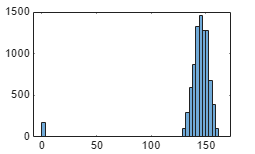

% Burnside
histogram(burnsideData.("616.18"));

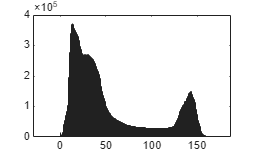


% Gault
histogram(gaultData.Variables);


[sigDiffFull, pFull] = ttest2(synchBurn.Variables, synchGault.Variables);
[sigDiffClear, pClear] = ttest2(synchClearBurn.Variables, synchClearGault.Variables);
[sigDiffCloudy, pCloudy] = ttest2(synchCloudyBurn.Variables, synchCloudyGault.Variables);

wavenumberSignificance = table(sigDiffFull', pFull', sigDiffClear', pClear', sigDiffCloudy', pCloudy', 'VariableNames', {'sigDiffFull', 'pFull', 'sigDiffClear', 'pClear', 'sigDiffCloudy', 'pCloudy'});
writetable(wavenumberSignificance, 'Wavenumber Significance.csv');

# Run a Basic Time Series Analysis

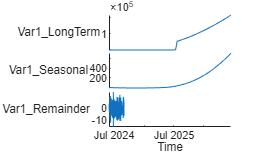

% Decompose the trend for each of the bands!
carbonTimeTable = timetable(averageDivFull.Time, averageDivFull.Carbon);
carbonTrends = trenddecomp(carbonTimeTable, 'stl', hours(24));


% Plot each as a stack plot
stackedplot(carbonTrends)